# **Problem 1:**

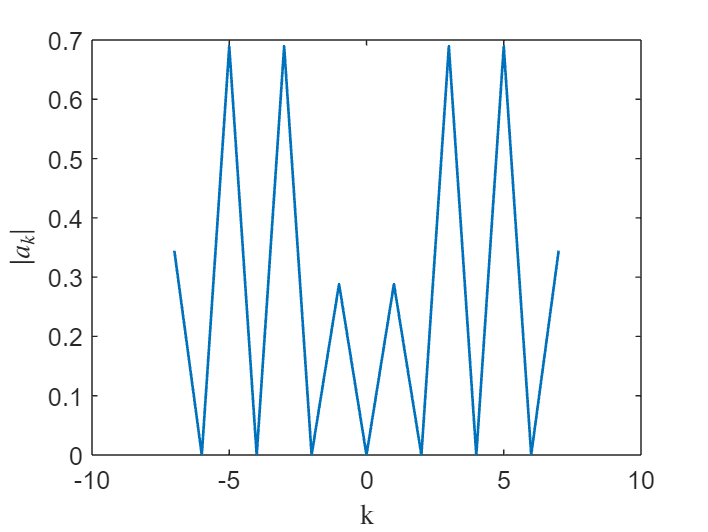

clc;
clear all;

syms t;
A=10;
T = 2* pi;
w0 = 2*pi/T;
k = -7:7 ;
kn = abs((1/T)*( int( (A*sin(t)*sin(k*w0*t)),t,0,pi/6 ) + int( (A/2)*sin(k*w0*t),t,pi/6 , 5*pi/6 ) + ...
    int ( (A*sin(t)*sin(k*w0*t)),t , 5*pi/6 , 7*pi/6 ) + int( (A/2)*sin(k*w0*t),t,7*pi/6 , 11*pi/6 ) + ...
    int ( (A*sin(t)*sin(k*w0*t)),t , 11*pi/6 , 2*pi )));

figure;
plot(k,kn,'LineWidth',1);
ylabel('$|a_k|$','FontWeight','bold','Interpreter','latex');
xlabel({'k'},'FontWeight','bold','Interpreter','latex');